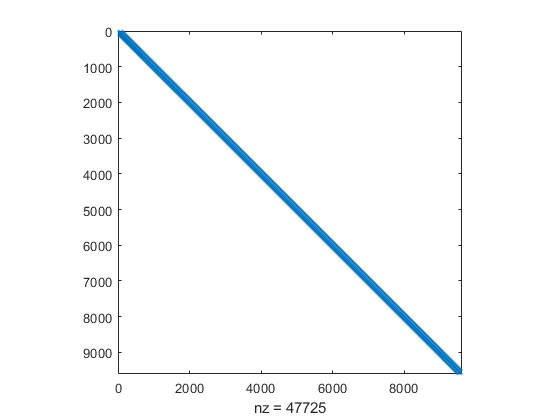

clear,clc,close all
n=100;
x=linspace(0,1,n);
y= linspace(0,1,n);
T_u=100;
T_d=0;
T_r=0;
T_l=0;
B=zeros((n-2)^2/2);
B1=zeros((n-2)^2);
b=linspace(4,4,(n-2)^2);
c=linspace(-1,-1,(n-2)^2-1);
d=c;
d(n-2:n-2:end)=0;
B1=B1+diag(b)+diag(d,1)+diag(c,-1);
a=linspace(1,1,(n-2)^2/2-(n-2)/2);
B2=B+diag(a,(n-2)/2)+diag(a,-1*(n-2)/2);
v2=[ -1 0; 0 -1];
A1=kron(B2,v2);
A=B1+A1;
spy(A)

BC=zeros((n-2)^2,1);
BC(n-1:n-2:(n-2)^2-(n-2)+1)=T_l;
BC(n-2:n-2:(n-2)^2)=T_r;
BC(1:n-2)=T_u;
BC((n-2)^2-(n-2)+1:end)=T_d;
C=inv(A)*BC

C =    57.2488
   75.8999
   83.4187
   87.1912
   89.4497
   90.9748
   92.0871
   92.9402
   93.6175
   94.1690


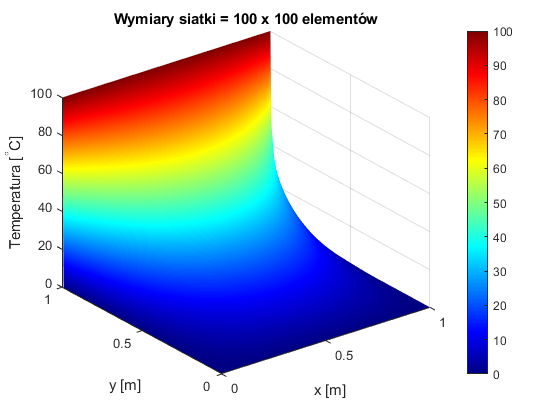

o=1;
for i=2:n-1
    for j=2:n-1
        T(i,j)=C(o);
        o=o+1;
    end
end
T(:,1)=T_l;
T(:,end+1)=T_r;
T(1,:)=T_u;
T(end+1,:)=T_d;
figure(2)
u=x((end):-1:1);
v=x((end):-1:1);
[X,Y]=meshgrid(u,v);
surf(X,Y,T)
colormap jet
shading interp
colorbar
xlabel('x [m]')
ylabel('y [m]')
zlabel('Temperatura [^{\circ}C]')
title(sprintf('Wymiary siatki = %.0f x %.0f elementów',n,n))

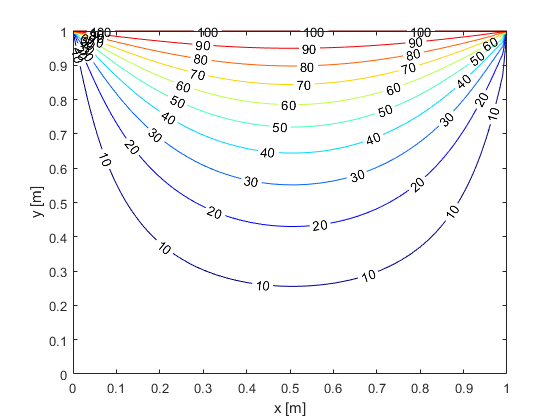

[F,D]=contour(u,v,T,'labelspacing', 80);
clabel(F,D)
xlabel('x [m]')
ylabel('y [m]')